clear all; close all;

## Params

a = 100 % Edge Length

a = 100

N = 20 % Number of LED's per segment

N = 20

## Calculate Corners

phi = (1 + sqrt(5))/2

phi = 1.6180

scale = (a * phi) / 2

scale = 80.9017


corners = [
% Orange    
1 1 1 % 1
1 1 -1
1 -1 1
1 -1 -1
-1 1 1
-1 1 -1
-1 -1 1
-1 -1 -1
% Green
0        phi    1/phi % 9
0        phi   -1/phi
0       -phi    1/phi
0       -phi   -1/phi
% Blue
 1/phi  0       phi % 13
 1/phi  0      -phi
-1/phi  0       phi
-1/phi  0      -phi
% Pink
 phi     1/phi  0 % 17
 phi    -1/phi  0
-phi     1/phi  0
-phi    -1/phi  0
];

corners = corners * scale;

## define edges

edgeCorners = [
% Lower V
14 16
16 8
8 12
12 4
4 14
16 6
6 10
10 2
2 14
%Standoffs
2 17
4 18
12 11
8 20
6 19
10 9
%Upper Ring
9 1
1 17
17 18
18 3
3 11
11 7
7 20
20 19
19 5
5 9
%Roof
1 13
3 13
7 15
5 15
15 13
];

leds = [];
t = linspace(0, 1, N+2);
for i=1:length(edgeCorners)    
    fullEdgeLeds = interp1([0 1], [corners(edgeCorners(i,1),:); corners(edgeCorners(i,2),:)] ,t);
    leds = [leds ; fullEdgeLeds(2:N+1,:)];
end


f1 = figure(1)

f1 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1096 630 560 420]
       Units: 'pixels'

  Show all properties


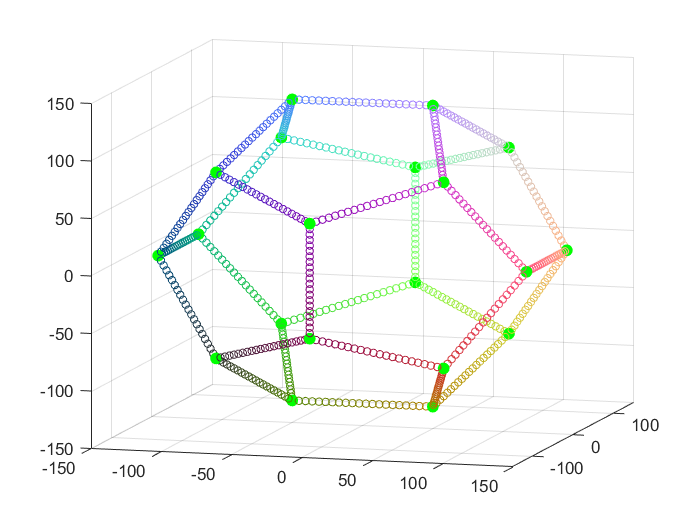

plot = scatter3(corners(:,1), corners(:,2), corners(:,3), 50, 'green', "filled");
hold on;
scatter3(leds(:,1), leds(:,2), leds(:,3),20, [rescale(leds(:,1),0,1), rescale(leds(:,2),0,1), rescale(leds(:,3),0,1)] );
xlim([-150 150]); ylim([-150 150]); zlim([-150 150]); 
view([16 11]);
%darkBackground(f1, [0.2 0.2 0.2], [0.9, 0.9, 0.9])


hold off;

Rotate around Y axis, to stand it up to a corner

alpha = acos(sqrt((5-sqrt(5))/10))/2 % angle to turn it by

alpha = 0.5086

alpha_d = rad2deg(alpha)

alpha_d = 29.1413


R = [cos(alpha)  0 sin(alpha)
      0           1 0 
      -sin(alpha) 0 cos(alpha)]

R =     0.8734         0    0.4870
         0    1.0000         0
   -0.4870         0    0.8734


Ry = transpose(R * transpose(corners)) 

Ry =   110.0576   80.9017   31.2650
   31.2650   80.9017 -110.0576
  110.0576  -80.9017   31.2650
   31.2650  -80.9017 -110.0576
  -31.2650   80.9017  110.0576
 -110.0576   80.9017  -31.2650
  -31.2650  -80.9017  110.0576
 -110.0576  -80.9017  -31.2650
   24.3482  130.9017   43.6711
  -24.3482  130.9017  -43.6711


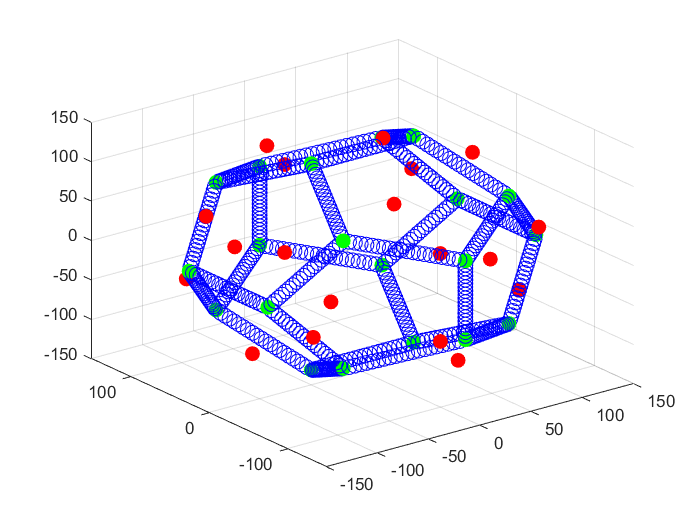


t = 100;
r = linspace(0, 1, t);
ticks = linspace(-150, 150, 6);
scatter3(corners(:,1), corners(:,2), corners(:,3), 80, 'green', "filled");
hold on;
scatter3(Ry(:,1), Ry(:,2), Ry(:,3), 80, 'Red', "filled");
scatter3(leds(:,1), leds(:,2), leds(:,3), 80, 'blue');

xlim([-150 150]); ylim([-150 150]); zlim([-150 150]); 
hold off;

RGB = zeros(size(leds))

RGB =      0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0



Points = [100 100 -150
         100 -100 -100
         -100 -100 -150];

alpha = deg2rad(0.3);

R = [cos(alpha)  0 sin(alpha)
      0           1 0 
      -sin(alpha) 0 cos(alpha)]

R =     1.0000         0    0.0052
         0    1.0000         0
   -0.0052         0    1.0000



M = [0 0 2]

M =      0     0     2




Plane = Points2plane(Points)

Plane =        10000      -10000      -40000    -6000000


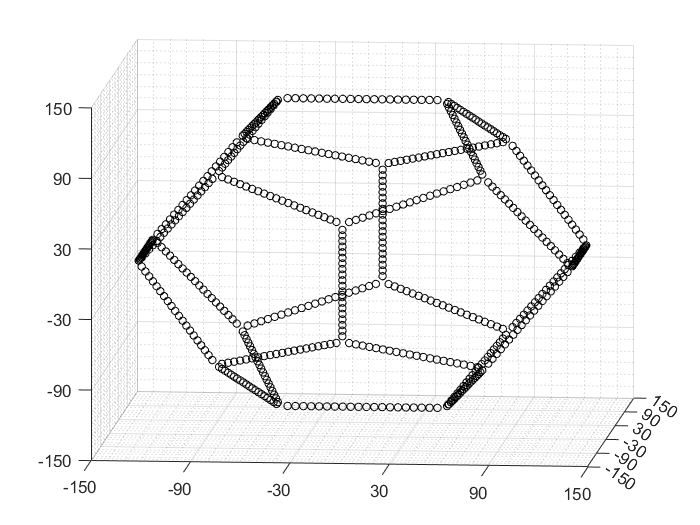

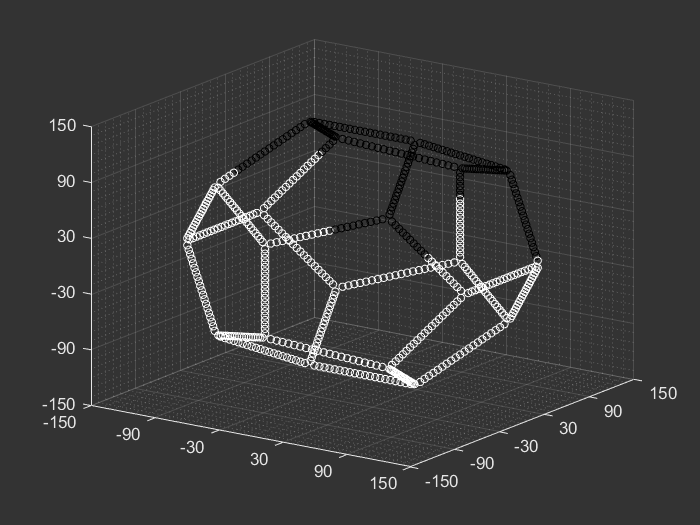


for i=1:t
    Points = transpose(R * transpose(Points));
    Points = Points + M;
    Plane = Points2plane(Points);


    RGB = lightAbovePlane(leds, RGB, Plane);
    %scatter3(leds(:,1), leds(:,2), leds(:,3),20, [0 .* rescale(leds(:,1),0,1), 0 .* rescale(leds(:,2),0,1), r(i) .* rescale(leds(:,3),0.1,3)] );
    scatter3(leds(:,1), leds(:,2), leds(:,3),20, [RGB(:,1), RGB(:,2), RGB(:,3)] ); hold On;
    %s2 = scatter3(Points(:,1), Points(:,2), Points(:,3), 50, 'Green');
    
    x = linspace(-150,150,5); y = linspace(-150,150,5);
    [X,Y] = meshgrid(x,y);
    Z = (-Plane(4) - (Plane(1)*X) - (Plane(2)*Y))/Plane(3);
    m = mesh(X,Y,Z,'EdgeAlpha', 0.5);
    
    
    
    xticks(ticks); yticks(ticks); zticks(ticks);
    xlim([-150 150]); ylim([-150 150]); zlim([-150 150]);
    view(5 + 0.3*i, 11+0.1*i);
    %view([16 11]);
    grid minor;
    f2 = figure(2);
    darkBackground(f2, [0.2 0.2 0.2], [0.9, 0.9, 0.9]);    
    drawnow
    pause(0.01);
    %delete(s2);
    delete(m);
end

function RGB = lightAbovePlane(LED, RGB, plane)
    arguments
        LED(:,3) {mustBeNumeric, mustBeFinite}
        RGB(:,3) {mustBeNumeric, mustBeFinite, mustBeEqualSize(RGB,LED)}
        plane(1,4) {mustBeNumeric, mustBeFinite}
    end

    dx = plane(1);
    dy = plane(2);
    dz = plane(3);
    q = plane(4);

    for i=1:length(LED)
        if(LED(i,1) * dx + LED(i,2) * dy + LED(i,3) * dz + q > 0)
            RGB(i,:) = [1, 1, 1];
        else
            RGB(i,:) = [0, 0, 0];
        end
    end
end

function plane = Points2plane(Points)
    arguments
        Points(3,3) {mustBeNumeric, mustBeFinite}
    end
    
    normal = cross(Points(1,:) - Points(2,:), Points(1,:) - Points(3,:));
    d = Points(1,1)*normal(1) + Points(1,2)*normal(2) + Points(1,3)*normal(3);
    d = -d;
    plane = [normal, d];
end


% Custom validation function
function mustBeEqualSize(a,b)
    % Test for equal size
    if ~isequal(size(a),size(b))
        eid = 'Size:notEqual';
        msg = 'Size of first input must equal size of second input.';
        throwAsCaller(MException(eid,msg))
    end
end

